%% 8번 문제
clear; clc;

rng('default');
num_sims = 100000;

% (a) 
rand_matrix = rand(num_sims, 5);

% (b) 
p_modules = [0.72, 0.81, 0.67, 0.90, 0.76];
% 행렬의 각 열에 대응하는 확률 벡터 원소를 비교 (브로드캐스팅 적용)
detection_matrix = rand_matrix <= p_modules; 

% (c) 
detected_counts = sum(detection_matrix, 2);

% (d) 
system_success = detected_counts >= 3;
system_prob = mean(system_success);

fprintf('=== 8번 결과 ===\n');

=== 8번 결과 ===


fprintf('시스템 감지 확률(3개 이상 모듈 감지): %.2f%%\n', system_prob * 100);

시스템 감지 확률(3개 이상 모듈 감지): 92.42%


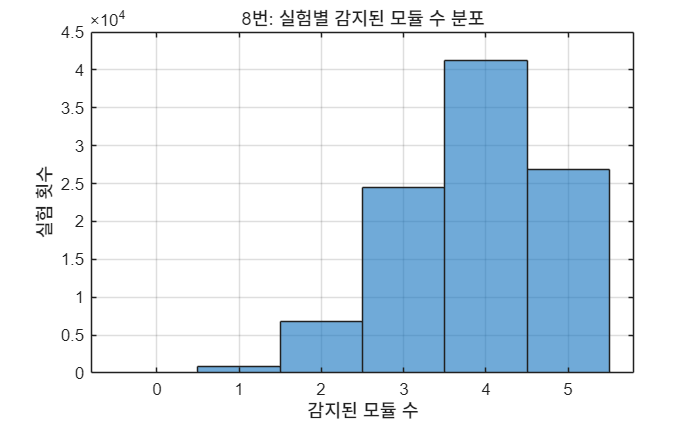


% (e) 
figure(9);
histogram(detected_counts, 'BinMethod', 'integers');
title('8번: 실험별 감지된 모듈 수 분포');
xlabel('감지된 모듈 수');
ylabel('실험 횟수');
xticks(0:5);
grid on;